**Parkinson's Freezing of Gait Prediction**

Computation of the Information Geometry of time-series data.

Application: [https://www.kaggle.com/competitions/tlvmc-parkinsons-freezing-gait-prediction](https://www.kaggle.com/competitions/tlvmc-parkinsons-freezing-gait-prediction)

## **Problem**

Detect freezing of gait (FOG), a debilitating symptom that afflicts many people with Parkinson’s disease. 

## **Methodology**:

Given a time-series $\chi = (x[T_s],x[2T_s],x[3T_s],\dots)$ such that $T_s$ is the sampling period we define its Information Length as follows 

$\mathcal{L}[n]=T_s\sum_{k=0}^{n}\Gamma[kT_s]$,

$\Gamma[kT_s]^2=\frac{4s}{T_s^2}\sum_{j}\left(\sqrt{P[j;(k)T_s]}-\sqrt{P[j;(k-1)T_s]}\right)$.

where $\Gamma$ is the information rate, i.e. the speed of the statistical description of the time-series. $T_s ,k,$ and $s$ denote the sampling period, the discrete time and the spatial step size of the space variable $x$ in the probability mass function (PMF) $P\left\lbrack j;{\textrm{kT}}_s \right\rbrack$.

## Data

table_2365c918c9=readtable('/home/ag1028/Documents/Exeterunijob/Piotr/tlvmc-parkinsons-freezing-gait-prediction/train/tdcsfog/2365c918c9.csv')

table_2365c918c9 = 6659×7 table
    Time     AccV       AccML      AccAP     StartHesitation    Turn    Walking
    ____    _______    _______    _______    _______________    ____    _______

      0     -8.9581    0.91959    -3.3301           0            0         0   
      1     -8.9517    0.91492    -3.3733           0            0         0   
      2      -8.948    0.92596    -3.3783           0            0         0   
      3     -8.9088    0.92558    -3.4319           0            0         0   
      4      -8.927    0.91227    -3.4232           0            0         0   
      5     -8.9264    0.91468    -3.4318           0            0         0   
      6     -8.9288    0.91014    -3.4025           0            0         0   
      7  

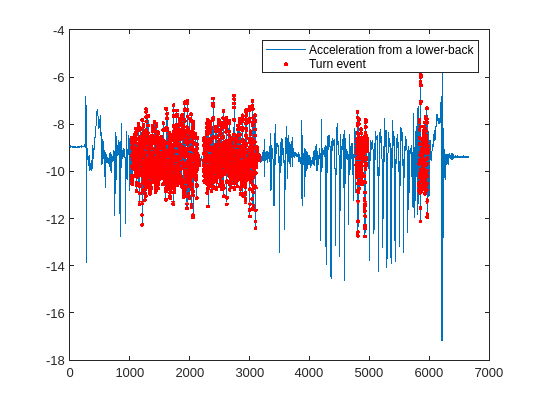

plot(table_2365c918c9.Time,table_2365c918c9.AccV)
hold on
idx=table_2365c918c9.Turn==1;
plot(table_2365c918c9.Time(idx),table_2365c918c9.AccV(idx),'r.')
legend('Acceleration from a lower-back','Turn event')

#### Information Rate plot (example)

## PDF initialization

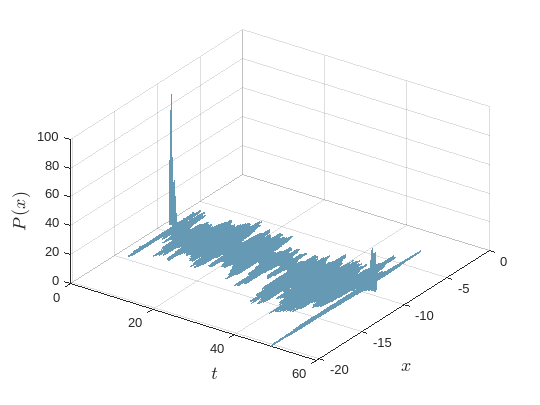

N=100; %Window size
t=0.0078*table_2365c918c9.Time;
n_pdfs=numel(table_2365c918c9.Time)-(N);
pdf=zeros(n_pdfs,N);
xi=zeros(n_pdfs,N);
[pdf(1,:),xi(1,:)]  = ksdensity(table_2365c918c9.AccV(1:N));
Energy=zeros(length(pdf(:,1)),1);
figure
set(gcf,'color','w');
xlabel('$t$','Interpreter','Latex','FontSize', 14);
zlabel('$P(x)$','Interpreter','Latex','FontSize', 14);
ylabel('$x$','Interpreter','Latex','FontSize', 14);
grid on
hold on
for i = 2:n_pdfs-1
    [pdf(i,:),xi(i,:)]  = ksdensity(table_2365c918c9.AccV(i:N+i));
    plot3(t(N+i)*ones(1,N),xi(i,:),pdf(i,:),'color',[0.4 0.6 0.7])
    Ts=t(N+i)-t(N+i-1);
    Energy(i)=trapz(4*((sqrt(pdf(i,:))-sqrt(pdf(i-1,:))).^2)./(Ts^2));
end
view([35.0 42.7])

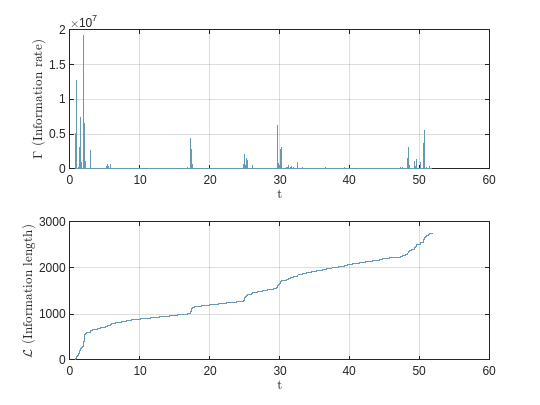

% Information length computation
figure
set(gcf,'color','w');
IL=cumtrapz(t(N+1:end),sqrt(Energy)); %equation (3.8)
subplot(2,1,1)
    plot(t(N+1:end),Energy,'color',[0.4 0.6 0.7]);
    xlabel('t','Interpreter','Latex','FontSize', 10)
    ylabel('$\Gamma$ (Information rate)','Interpreter','Latex','FontSize', 10)
    grid on
subplot(2,1,2)
    plot(t(N+1:end),IL,'color',[0.4 0.6 0.7]);
    xlabel('t','Interpreter','Latex','FontSize', 10)
    ylabel('$\mathcal{L}$ (Information length)','Interpreter','Latex','FontSize', 10)
    grid on

## Research questions

- How can the information rate and length help classifying the different events present in the time-series?